a = imread("insectos\Butterfly\google0.jpg");
ar_ = a(:,:,1);
lin = 58;
pl = ar_(lin,:);
ar_(lin,:) = 0;
% Convolucion
k = [1 1 1 1 1 1];
c = conv(pl,k)

c =           98          98         112         112         119         128         174         365         578         804        1026        1252        1351        1409        1436        1465        1491        1511        1523        1528        1518        1495        1464        1432        1385        1169         972         752         561         375         213         190         149         142         114          83          46          41          46          52          57          61          64          54          69          86         156         295         438         505



figure(1), subplot(3,1,1), image(ar_), title('Imagen Original'), colormap gray(256);
figure(1), subplot(3,1,2), plot(pl), title("Perfil de Linea");
figure(1), subplot(3,1,3), plot(c), title("Convolucion-perfil");

Kernel

ar = double(a(:,:,1));
s = size(a);
arc = ar*0;
arcmediana = ar*0;
kernel = [1 1 1;1 1 1;1 1 1]/9;
kernelgauss = [1 2 1;2 4 2;1 2 1]/16;
for i = 2:s(1)-1
    for j = 2:s(2)-1
        ventana = ar(i-1:i+1,j-1:j+1);
        prod = ventana .* kernelgauss;
        pix =sum(sum(prod));
        arc(i,j) = pix;
        % Mediana
        vector = ventana(:);
        vector = sort(vector);
        arcmediana(i,j) = vector(5);
    end
end
figure(2), subplot(3,1,1), imshow(uint8(ar)), title('Imagen Original'), colormap gray(256);
figure(2), subplot(3,1,2), imshow(uint8(arc)), title("Perfil conv");

Eliminacion de altas frecuencias:

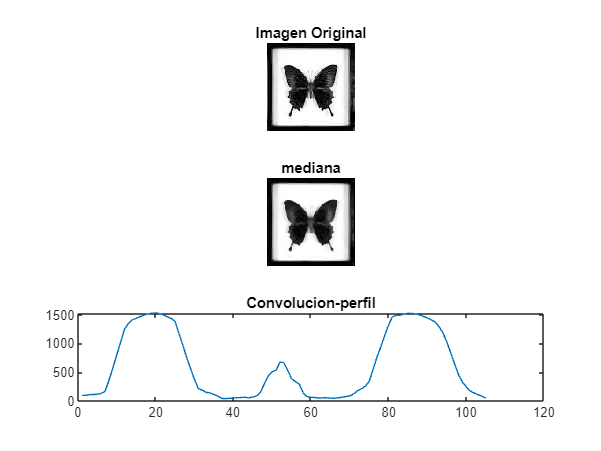

altfre = ar - arc;
figure(3),imshow(uint8(altfre)), title("Perfil conv");
figure(4),imshow(uint8(arcmediana)), title("mediana");